clear all
close all
dir

.                      App_trainClassifier.m  lrCostFunction.m       sigmoid.m              titanicchallenge.mlx   
..                     data.txt               lrpredict.m            theta.txt              



% Load saved matrices from file
titanickaggle = load('data.txt');

% The matrices x and y will now be in your MATLAB environment
[m, n] = size(titanickaggle);

x = titanickaggle(:,1:n-1);
y = titanickaggle(:,n);

%training set
xtrain = x(1:round(m*0.70),:); 
ytrain = y(1:round(m*0.70),:);

%validation set
%xval = x(round(m*0.70)+1:round(m*0.85),:);
%yval = y(round(m*0.70)+1:round(m*0.85),:);

%test set
xtest = x(round(m*0.70)+1:end,:);
ytest = y(round(m*0.70)+1:end,:);

%App from logistic regression
[trainedClassifier, validationAccuracy] = logit_trainClassifier(xtrain, ytrain);

%try using the trained classifier in data unknown for the model
pred_test = trainedClassifier.predictFcn(xtest);

%calculating the recall, precision and F1 score of the test set
true_earth = sum(double(ytest == 1));
predicted_earth = sum(double(pred_test == 1));
true_positive = sum(double(ytest == 1) .* double(pred_test == 1));
precision = true_positive/predicted_earth;
recall = true_positive/true_earth;
F1score = 2*precision*recall/(recall+precision);
%fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred_train == ytrain)) * 100);
%fprintf('\n Test Set Accuracy: %f\n', mean(double(pred_test == ytest)) * 100);
fprintf('\n **********************************\n Test Set Accuracy: %f\n **********************************\n Test Set Precision = %f\n **********************************\n Test Set Recall = %f\n **********************************\n Test Set F1score = %f\n **********************************\n', mean(double(pred_test == ytest)), precision, recall, F1score);


 **********************************
 Test Set Accuracy: 0.782772
 **********************************
 Test Set Precision = 0.715909
 **********************************
 Test Set Recall = 0.656250
 **********************************
 Test Set F1score = 0.684783
 **********************************


%App from KNN method
[trainedClassifier, validationAccuracy] = KNN_trainClassifier(xtrain, ytrain);

%try using the trained classifier in data unknown for the model
pred_test = trainedClassifier.predictFcn(xtest);

%calculating the recall, precision and F1 score of the test set
true_earth = sum(double(ytest == 1));
predicted_earth = sum(double(pred_test == 1));
true_positive = sum(double(ytest == 1) .* double(pred_test == 1));
precision = true_positive/predicted_earth;
recall = true_positive/true_earth;
F1score = 2*precision*recall/(recall+precision);
%fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred_train == ytrain)) * 100);
%fprintf('\n Test Set Accuracy: %f\n', mean(double(pred_test == ytest)) * 100);
fprintf('\n **********************************\n Test Set Accuracy: %f\n **********************************\n Test Set Precision = %f\n **********************************\n Test Set Recall = %f\n **********************************\n Test Set F1score = %f\n **********************************\n', mean(double(pred_test == ytest)), precision, recall, F1score);


 **********************************
 Test Set Accuracy: 0.805243
 **********************************
 Test Set Precision = 0.797297
 **********************************
 Test Set Recall = 0.614583
 **********************************
 Test Set F1score = 0.694118
 **********************************


% Load saved matrices from file
xtitanictest = load('datatest.txt');

%Make a prediction from the test data given by kaggle
titanic_test = trainedClassifier.predictFcn(xtitanictest);

csvwrite('titanic_test.txt', titanic_test);

lambda = 27;
[m, n] = size(xtrain);
%[all_theta] = oneVsAll(xtrain, ytrain, num_labels, lambda);

% You need to return the following variables correctly
theta = zeros(n + 1, 1);

% Add ones to the X data matrix
xtrain = [ones(m, 1) xtrain];
%xval = [ones(m, 1) xval];

%logistic regression classifiers with regularization parameter lambda
initial_theta = zeros(n + 1, 1);
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 400);

[theta] = fminunc(@(t)(lrCostFunction(t, xtrain, ytrain ,lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


%Calculate Accuracy
pred_train = lrpredict(theta, xtrain);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred_train == ytrain)) * 100);


Training Set Accuracy: 79.006410



[q, r] = size(xtest);

xtest = [ones(q, 1) xtest];

error_test = lrCostFunction(theta, xtest, ytest, 0);

disp(error_test);

    0.4894




pred_test = lrpredict(theta, xtest);
fprintf('\nTest Set Accuracy: %f\n', mean(double(pred_test == ytest)) * 100);


Test Set Accuracy: 79.850746


%Calculate Precision, Recall and F score
true_dead = sum(double(ytest == 1))

true_dead = 47

predicted_dead = sum(double(pred_test == 1))

predicted_dead = 46

true_positive = sum(double(ytest == 1) .* double(pred_test == 1))

true_positive = 33

precision = true_positive/predicted_dead

precision = 0.7174

recall = true_positive/true_dead

recall = 0.7021

F1score = 2*precision*recall/(recall+precision)

F1score = 0.7097

csvwrite('theta.txt', theta);

% Number of training examples
[o, p] = size(xval);

% Add ones to the X data matrix
xval = [ones(o, 1) xval];

% You need to return these values correctly
error_train = zeros(o, 1);
error_val   = zeros(o, 1);

%training errors in error_train and the cross validation errors in error_val
for i = 1:o
   [theta] = fminunc(@(t)(lrCostFunction(t, xtrain(1:i, :), ytrain(1:i) ,lambda)), initial_theta, options);
   error_train(i) = lrCostFunction(theta, xtrain(1:i, :), ytrain(1:i), 0);
   error_val(i) = lrCostFunction(theta, xval(1:i, :), yval(1:i), 0);
end


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:o
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000001	0.000001
  	2		0.000002	0.106712
  	3		0.000001	0.002413
  	4		0.000001	0.057958
  	5		0.000002	0.002352
  	6		0.000001	0.000920
  	7		0.000001	2.151732
  	8		0.000001	1.635107
  	9		0.000001	3.102268
  	10		0.000002	2.472392
  	11		0.000001	3.466325
  	12		0.000001	2.931554
  	13		0.000001	2.892449
  	14		0.000001	2.823260
  	15		0.055032	5.755309
  	16		0.057852	4.375372
  	17		0.044996	4.775811
  	18		0.082308	Inf
  	19		0.147760	NaN
  	20		0.076651	Inf
  	21		0.090728	NaN
  	22		0.065692	Inf
  	23		0.062988	Inf
  	24		0.061317	Inf
  	25		0.092129	Inf
  	26		0.087378	Inf
  	27		0.084847	Inf
  	28		0.081213	Inf
  	29		0.080789	Inf
  	30		0.076265	Inf
  	31		0.223365	1.262079
  	32		0.222135	1.124626
  	33		0.216516	1.105077
  	34		0.210242	1.079121
  	35		0.204737	1.079250
  	36		0.202499	1.057553
  	37		0.264388	1.088403
  	38		0.258159	1.067172
  	39		0.252575	1.070609
  	40		0.258714	1.038108
  	41		0.254271	1.175843
  	42		0.284746	1.084092
  	43		0.287508	1.066007

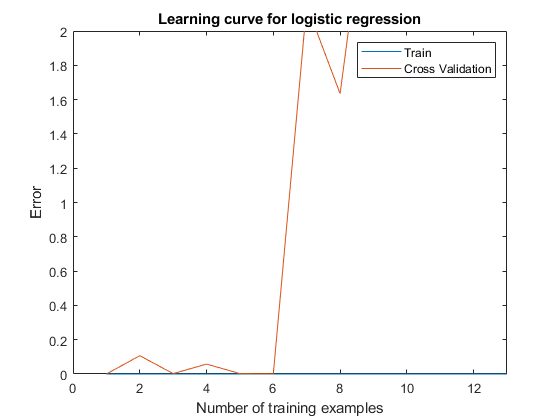


plot(1:o, error_train, 1:o, error_val);
title('Learning curve for logistic regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 2])

% Selected values of lambda (you should not change this)
lambda_vec = [0.001 0.01 0.1 1 3 9 27 70 100]';

% You need to return these variables correctly.
error_train = zeros(length(lambda_vec), 1);
error_val = zeros(length(lambda_vec), 1);

options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 400);

for i = 1:size(lambda_vec,1)
   [theta] = fminunc(@(t)(lrCostFunction(t, xtrain, ytrain ,lambda_vec(i))), initial_theta, options);
   error_train(i) = lrCostFunction(theta, xtrain, ytrain, 0);
   error_val(i) = lrCostFunction(theta, xval, yval, 0);
end


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

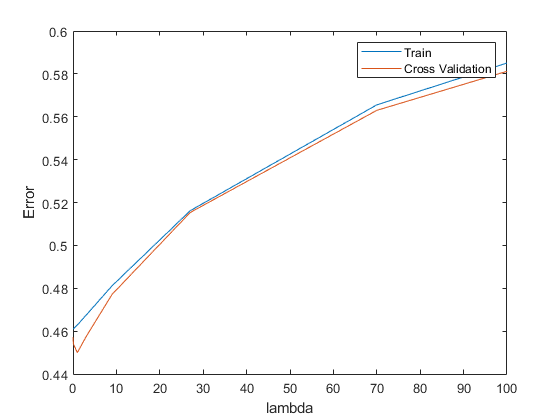

plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');

for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

lambda		Train Error	Validation Error


0.001000	0.461028	0.457144
0.010000	0.461028	0.456778
0.100000	0.461090	0.453950
1.000000	0.462871	0.449970
3.000000	0.467402	0.457363
9.000000	0.481158	0.477139
27.000000	0.516180	0.515345
70.000000	0.565551	0.562990
100.000000	0.585057	0.581212


minimum_err = zeros(size(lambda_vec));
for i = 1:length(lambda_vec)
    minimum_err(i) = abs(error_train(i)-error_val(i));
    if i == 1
        fprintf('lambda\t\tError\n');
    end
    fprintf('%f\t%f\n',lambda_vec(i), minimum_err(i));
end

lambda		Error


0.001000	0.003884
0.010000	0.004251
0.100000	0.007139
1.000000	0.012901
3.000000	0.010039
9.000000	0.004019
27.000000	0.000835
70.000000	0.002561
100.000000	0.003846


min(minimum_err)

ans = 8.3511e-04